# Slosh 2D - Tilt y

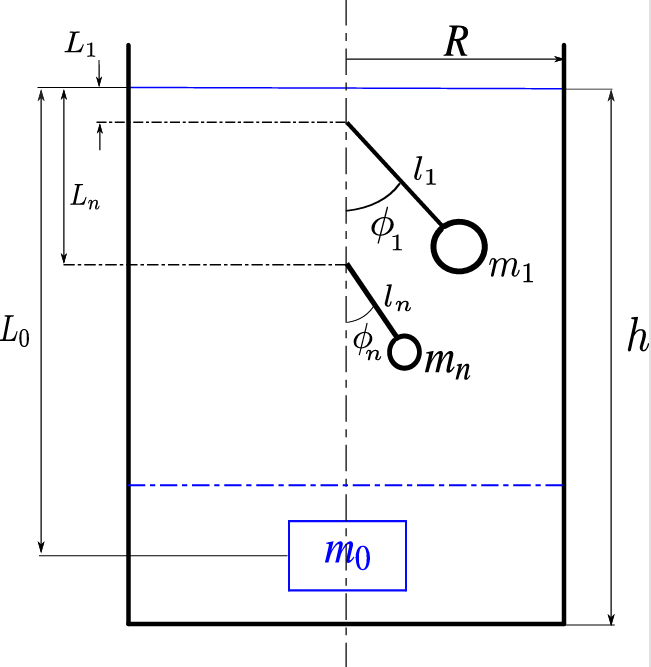

In this code the equation of motion for the pendulum angles representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent the 1D motion of the pivot, but it is the same for any point with a displacement along z of the cylinder axis.

clc 
clear all

syms psi_n(t) psi(t)
syms t 
syms h L_n L_0 l_n m_n m_0 g
syms x z

$\psi_n$ = rotation about Y describing the sloshing

$\psi$ = pitch rotation about the y axis of the container

$l_n$ = length of pendulum

$m_n$ = mass of pendulum

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid mass in the world reference frame. 

% Tilt rotation about y of - psi
R_y_psi = [cos(-psi), sin(-psi);
           -sin(-psi),  cos(-psi)];

R = R_y_psi

$$R(t) = \left(\begin{array}{cc} \cos\left(\psi \left(t\right)\right) & -\sin\left(\psi \left(t\right)\right)\\ \sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [0; 0];

Define the transformation

T_wc = [R, p; 0 0 1];
T_wc = formula(T_wc);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_wc);

$$\left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right) & -\sin\left(\psi \left(t\right)\right) & 0\\ \sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

### Homogeneous Transformation from inertial frame to pivot

% Second rotation about y
R_y_psin = [cos(-psi_n), sin(-psi_n);
            -sin(-psi_n),  cos(-psi_n)];

R = R_y_psin

$$R(t) = \left(\begin{array}{cc} \cos\left(\psi_{n}\left(t\right)\right) & -\sin\left(\psi_{n}\left(t\right)\right)\\ \sin\left(\psi_{n}\left(t\right)\right) & \cos\left(\psi_{n}\left(t\right)\right) \end{array}\right)$$

Define translation vector (distance of center of rotation from the container base frame)

p = [0; -(h/2 - L_n)];

Define the transformation

T_cp = [R, p; 0 0 1];
T_cp = formula(T_cp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_cp);

$$\left(\begin{array}{ccc} \cos\left(\psi_{n}\left(t\right)\right) & -\sin\left(\psi_{n}\left(t\right)\right) & 0\\ \sin\left(\psi_{n}\left(t\right)\right) & \cos\left(\psi_{n}\left(t\right)\right) & L_{n}-\frac{h}{2}\\ 0 & 0 & 1 \end{array}\right)$$

### Homogeneous Transformation from pivot to mass

Define translation vector

p = [0; l_n];

Homogeneous transformation

T_pm = [eye(2), p; 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & l_{n}\\ 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wc*T_cp*T_pm;
% T_wm = T_cp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,3);
xm = simplify(xm)

$$xm = -\sin\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)-l_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)$$

zm = T_wm(2,3);
zm = simplify(zm)

$$zm = \cos\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)+l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)$$

Pendulum mass wrt pivot

Tr = T_cp*T_pm;

**If **$R_y(\theta)$**:**


$$p_m =$$

$$\left(\begin{array}{c}
-l\,\sin \left(\theta \left(t\right)\right)\\
0\\
-l\;\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


**If **$R_y(-\theta)$**:**


$$p_m =$$

$$\left(\begin{array}{c}
l\,\sin \left(\theta \left(t\right)\right)\\
0\\
-l\;\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the liquid mass in the world reference frame. 

### Homogeneous Transformation from inertial frame to pivot

Define translation vector (distance of center of rotation from the container base frame)

p = [0; -(h/2 - L_0)];

Define the transformation

T_c0 = [eye(2), p; 0 0 1];
T_c0 = formula(T_c0);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from center of mass to m0:');

Homogeneous Transformation Matrix from center of mass to m0:


disp(T_c0);

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & L_{0}-\frac{h}{2}\\ 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_w0 = T_wc*T_c0;

Derive the coordinates of the pendulum mass

x0 = T_w0(1,3);
z0 = T_w0(2,3);

x0 = simplify(x0)

$$x0 = -\sin\left(\psi \left(t\right)\right)\,\left(L_{0}-\frac{h}{2}\right)$$

z0 = simplify(z0)

$$z0 = \cos\left(\psi \left(t\right)\right)\,\left(L_{0}-\frac{h}{2}\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t)

$$xm\_dot = -l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)\,\frac{\partial }{\partial t}\psi \left(t\right)$$

zm_dot = diff(zm, t)

$$zm\_dot = -l_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)-\sin\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)\,\frac{\partial }{\partial t}\psi \left(t\right)$$


x0_dot = diff(x0, t)

$$x0\_dot = -\cos\left(\psi \left(t\right)\right)\,\left(L_{0}-\frac{h}{2}\right)\,\frac{\partial }{\partial t}\psi \left(t\right)$$

z0_dot = diff(z0, t)

$$z0\_dot = -\sin\left(\psi \left(t\right)\right)\,\left(L_{0}-\frac{h}{2}\right)\,\frac{\partial }{\partial t}\psi \left(t\right)$$

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m_n * xm_dot^2;
% Tmx = simplify(Tmx)
% 
Tmz = 0.5 * m_n * zm_dot^2;
% Tmz = simplify(Tmz)

T0x = 0.5 * m_0 * x0_dot^2;
% T0x = simplify(T0x)

T0z = 0.5 * m_0 * z0_dot^2;
% T0z = simplify(T0z)



% Tm = Tmx + Tmz + T0x + T0z
Tm = Tmx + T0x

$$Tm = \frac{m_{n}\,{\left(l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}}{2}+\frac{m_{0}\,{\cos\left(\psi \left(t\right)\right)}^{2}\,{\left(L_{0}-\frac{h}{2}\right)}^{2}\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}}{2}$$


T = Tm;


$$T_m =\frac{m\,{{\left(-\frac{\partial }{\partial t}\mathrm{\ }\textrm{xt}\left(t\right)+\textrm{dy}\,\cos \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+\textrm{dx}\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)-l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }\textrm{zt}\left(t\right)+l\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }\textrm{yt}\left(t\right)+\textrm{dx}\,\cos \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)-\textrm{dy}\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)-l\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)-l\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)\right)}}^2 }{2}$$


### Potential energy

%% Potential energy
Um = m_n * g * zm + m_0 * g * z0;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m_{n}\,\left(\cos\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)+l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)+g\,m_{0}\,\cos\left(\psi \left(t\right)\right)\,\left(L_{0}-\frac{h}{2}\right)$$


$$U=g\,m\,{\left(h+\textrm{zt}\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)\right)}-M\,g\,{\left(\textrm{dz}-\textrm{zt}\left(t\right)\right)}$$


### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)

$$L = \frac{m_{n}\,{\left(2\,l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}}{8}-g\,m_{n}\,\left(\cos\left(\psi \left(t\right)\right)\,\left(L_{n}-\frac{h}{2}\right)+l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)+\frac{m_{0}\,{\cos\left(\psi \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\,{\left(2\,L_{0}-h\right)}^{2}}{8}-g\,m_{0}\,\cos\left(\psi \left(t\right)\right)\,\left(L_{0}-\frac{h}{2}\right)$$


% wrt theta
L_thetadot = diff(L, diff(psi_n(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, psi_n(t));
L_theta = simplify(L_theta)

$$L\_theta = g\,l_{n}\,m_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)-\frac{l_{n}\,m_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)}{2}$$

### Equation of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$\frac{l_{n}\,m_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial^{2}}{\partial t^{2}}\psi_{n}\left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)\right)-2\,l_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi_{n}\left(t\right)+\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}-\sin\left(\psi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\,\left(2\,L_{n}-h\right)+\cos\left(\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)\right)}{2}-g\,l_{n}\,m_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

\frac{l_{n}\,m_{n}\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\left(\frac{\partial ^2}{\partial t^2} \psi _{n}\left(t\right)+\frac{\partial ^2}{\partial t^2} \psi \left(t\right)\right)-2\,l_{n}\,\sin\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \psi _{n}\left(t\right)+\frac{\partial }{\partial t} \psi \left(t\right)\right)}^2-\sin\left(\psi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \psi \left(t\right)\right)}^2\,\left(2\,L_{n}-h\right)+\cos\left(\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)\,\frac{\partial ^2}{\partial t^2} \psi \left(t\right)\right)}{2}-g\,l_{n}\,m_{n}\,\sin\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)




syms c_psi_n s_psi_n c_psi s_psi c_theta_beta s_theta_beta
syms psi_n_dot psi_n_ddot psi_dot psi_ddot x_ddot  
% eq_sub1 = subs(eqn_theta,[cos(psi_n(t)), sin(psi_n(t)), cos(psi(t)),sin(psi(t))],[c_psi_n s_psi_n c_psi s_psi]);
% eq_sub2 = subs(eqn_theta, [diff(diff(psi_n(t),t),t),diff(diff(psi(t),t),t),diff(diff(x(t),t),t)],[psi_n_ddot,psi_ddot,x_ddot ]);
eq_sub2 = subs(eqn_theta, [diff(diff(psi_n(t),t),t),diff(diff(psi(t),t),t)],[psi_n_ddot,psi_ddot ]);

eq_sub3 = subs(eq_sub2, [diff(psi_n(t),t),diff(psi(t),t)],[psi_n_dot,psi_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
% eqn1 = isolate(eq_sub3 == 0, psi_n_ddot);
eqn1 = collect(eq_sub3, [x_ddot, g, psi_dot^2, psi_ddot, psi_n_dot]);

disp(eqn1);

$$\left(-l_{n}\,m_{n}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)\,g+\left(-\frac{l_{n}\,m_{n}\,\sin\left(\psi \left(t\right)\right)\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)}{2}\right)\,{\dot{\psi }}^{2}+\frac{l_{n}\,m_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)\right)}{2}\,\ddot{\psi }+\left(-{l_{n}}^{2}\,m_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)\,{\psi_{\dot{n}}}^{2}+\left(-2\,{l_{n}}^{2}\,m_{n}\,\dot{\psi }\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)\,\psi_{\dot{n}}-\frac{l_{n}\,m_{n}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,{\dot{\psi }}^{2}\,\sin\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)-2\,l_{n}\,\psi_{\ddot{n}}\,\cos\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)}{2}$$

disp(latex(eqn1));

\left(-l_{n}\,m_{n}\,\sin\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\right)\,g+\left(-\frac{l_{n}\,m_{n}\,\sin\left(\psi \left(t\right)\right)\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)}{2}\right)\,{\dot{\psi }}^2+\frac{l_{n}\,m_{n}\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\left(2\,L_{n}-h\right)\right)}{2}\,\ddot{\psi }+\left(-{l_{n}}^2\,m_{n}\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\sin\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\right)\,{\psi _{\dot{n}}}^2+\left(-2\,{l_{n}}^2\,m_{n}\,\dot{\psi }\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\sin\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\right)\,\psi _{\dot{n}}-\frac{l_{n}\,m_{n}\,\cos\left(\psi _{n}\left(t\right)+\psi \left(t\right)\right)\,\left(2\,l_{n}\,{\dot{\psi }}^2\,\sin


eq_sub1 = subs(eq_sub3,[cos(psi_n(t)), sin(psi_n(t)), cos(psi(t)),sin(psi(t)),cos(psi_n(t)+psi(t)), sin(psi_n(t)+psi(t)), psi_dot^2, m_n],[1 psi_n 1 psi 1 psi_n+psi 0 1]);
eqn1 = collect(eq_sub1, [x_ddot, g, psi_ddot, psi_n_dot]);
disp(eqn1);

$$\left(-l_{n}\,\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)\,g+\frac{l_{n}\,\left(2\,L_{n}-h+2\,l_{n}\right)}{2}\,\ddot{\psi }+\left(-{l_{n}}^{2}\,\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)\,{\psi_{\dot{n}}}^{2}+\left(-2\,{l_{n}}^{2}\,\dot{\psi }\,\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)\,\psi_{\dot{n}}+\frac{l_{n}\,\left(2\,l_{n}\,\psi_{\ddot{n}}-2\,l_{n}\,{\dot{\psi }}^{2}\,\left(\psi_{n}\left(t\right)+\psi \left(t\right)\right)\right)}{2}$$

#### **For **$R_y(-\theta)$:

**If **$R_y(-\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


**If **$R_y(\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta -\theta \right)\,\ddot{x} +\frac{1}{l_n }\sin \left(\beta -\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


$l_n \ddot{\theta} +\ddot{x} +\left(\beta -\theta \right)g+{\left(l_n -\frac{h}{2}+L_n \right)}\,\ddot{\beta} \,$= 0

#### **For **$R_y(\theta)$:

**If **$R_y(-\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta -\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta -\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


**If **$R_y(\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} +\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$